## Fixed Point method

clear all;
close all;
clc;

Solve the equation $x^2-5=0$ to find the root $\epsilon = \sqrt 5$ using several different iterative methods

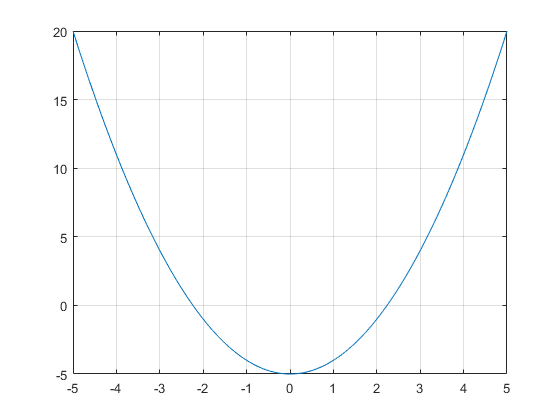

f = @(x) x.^2 - 5;
x = linspace(-5, +5, 1000);

figure();
plot(x, f(x));
grid on;

### 1.

xi = sqrt(5)

xi = 2.2361


phi1  = @(x) 5 + x - x.^2;
dphi1 = @(x) 1 - 2*x;
dphi1(xi)

ans = -3.4721

The absolute value of the derivative of phi at $x_i
$ is greater than 1: the method will not converge.

### 2.

phi2  = @(x) 5./x;
dphi2 = @(x) -5./x.^2;
dphi2(xi)

ans = -1.0000

The absolute value of the derivative of phi at $x_i
$ is equal to 1: no theoretical conclusion can be stated in this case.

### 3.

phi3  = @(x) 1 + x - 1/5*x.^2;
dphi3 = @(x) 1 - 2/5*x;
dphi3(xi)

ans = 0.1056

The absolute value of the derivative of phi at $x_i
$ is less than 1: the method will converge provided that the initial guess x{(0)} is close enough to $x_i
$ (local convergence).

### 4.

phi4 = @(x) 1/2*(x + 5./x);
dphi4 = @(x) 1/2 - 5./x.^2;
dphi4(xi)

ans = -0.5000

d2phi4 = @(x) 5./x.^3;
d2phi4(xi)

ans = 0.4472

The absolute value of the derivative of phi at $x_i
$ is less than 1: the second derivative is different from zero, so method 4 is expected to be of second order.

### Fixed point iterative method

Hyperparameters initialization

tol = 1e-6;
maxit = 1000;

#### 1.

x0 = xi + 0.001;
[xi1, x1] = fixed_point(phi1, x0, tol, maxit);
xi1

xi1 = -Inf

iter1 = numel(x1) - 1

iter1 = 1000

% The approximation xi is incorrect and the number of performed iterations is the maximum: as expected, the method did not converge.

%fixed_point_plot(phi1, x0, tol, 5);

#### 2.

x0 = 3;
[xi2, x2] = fixed_point(phi2, x0, tol, maxit);
xi2

xi2 = 3

iter2 = numel(x2) - 1

iter2 = 1000

% The approximation xi is incorrect and the number of performed iterations is the maximum: the method did not converge.

%fixed_point_plot(phi2, x0, tol, 5);

#### 3.

x0 = 4;
[xi3, x3] = fixed_point(phi3, x0, tol, maxit);
xi3

xi3 = 2.2361

iter3 = numel(x3) - 1

iter3 = 9


% The method converged to xi.

%fixed_point_plot(phi3, x0, tol, maxit);

% But the convergence is only local...

x0 = 10;
[xi3, x3] = fixed_point(phi3, x0, tol, maxit);
xi3

xi3 = -Inf

iter3 = numel(x3) - 1

iter3 = 1000

% With a different initial guess, the method may not converge to xi.

%fixed_point_plot(phi3, x0, tol, maxit);

#### 4.

x0 = 4;
[xi4, x4] = fixed_point(phi4, x0, tol, maxit);
xi4

xi4 = 2.2361

iter4 = numel(x4) - 1

iter4 = 5


% The method converged to xi.

%fixed_point_plot(phi4, x0, tol, maxit);

### Functions

#### Fixed point

function [xi, x_iter] = fixed_point(phi, x0, tol, maxit)
  %FIXED_POINT Find a root of the equation f(x) = 0 using the fixed point
  %   method x = phi(x), starting from the initial guess x0.
  %
  %   [xi, x_iter] = FIXED_POINT(phi, x0, tol, maxit)
  %
  %   Inputs  : phi     = function handle to the iteration function
  %             x0    = initial guess
  %             tol   = requested tolerance
  %             maxit = maximum number of iterations
  %   Output  : 
  %			xi = approximation of the root
  %			x_iter     = vector of the approximations of the root at each step

  x_iter(1) = x0;

  for iter = 1:maxit

    x_iter(iter+1) = phi(x_iter(iter));

    if (abs (x_iter(iter+1) - x_iter(iter)) < tol)
      break;
    end

  end
  
  xi = x_iter(end);

end

#### Fixed point plot

function fixed_point_plot(phi, x0, tol, maxit)
  %FIXED_POINT_PLOT Plot the function f and the evolution of the fixed point method.
  %
  %   FIXED_POINT_PLOT(phi, x0, tol, maxit)
  %
  %   Inputs  : phi     = function handle to the iteration function
  %             x0      = initial guess
  %             tol     = requested tolerance
  %             maxit   = maximum number of iterations

  [xi, x] = fixed_point(phi, x0, tol, maxit);
  a = min(x);
  b = max(x);
  
  figure
  hold on, box on
  x_plot = linspace(a, b, 1000);
  plot(x_plot, phi(x_plot), 'LineWidth', 2)
  plot(x_plot, x_plot, 'k-', 'LineWidth', 1)
  xlabel('x','FontSize', 16)
  ylabel('phi(x)','FontSize', 16)
  set(gca,'FontSize', 16)
  set(gca,'LineWidth', 1.5)
  pause
  
  old_color = 'kx-';
  new_color = 'gx-';
  for (iter = 1:length(x)-1)
    if (iter > 1)
        plot([x(iter-1) x(iter-1) x(iter)], [x(iter-1) x(iter) x(iter)], old_color, 'LineWidth', 2, 'MarkerSize', 8)
        plot([x(iter) x(iter) x(iter+1)], [x(iter) x(iter+1) x(iter+1)], new_color, 'LineWidth', 2, 'MarkerSize', 8)
        pause
    end
  end
end